# Modelowanie i symulacja w programie MATLAB cz.1

## Jan Rosa 410269 AiR

## Wstęp

Środowisko MATLAB stało się faktycznym standardem we współczesnych obliczeniach naukowo-technicznych, pozwalającym na przyspieszenie rozwiązywania różnorodnych problemów badawczych oraz inżynierskich. Przyspieszenie to jest osiągane przede wszystkim przez automatyzację rutynowych czynności obejmującą wszystkie fazy rozwiązywania danego zadania: od zbierania danych, poprzez ich analizę i rozwijanie algorytmów, do prezentacji wyników i wdrażania aplikacji. W ćwiczeniu przedstawione zostały wybrane zagadnienia związane z posługiwaniem się środowiskiem MATLAB.

### Zad a

Utwórz dwie zmienne (a i b), przypisz im wartości (23, 5). Następnie podziel większą liczbę przez mniejszą, a wynik zaokrąglij. Rezultat zapamiętaj w zmiennej c. Z kolei w zmiennej d zapamiętaj resztę z dzielenia. Wskazówka – aby znaleźć potrzebne funkcje skorzystaj z systemu pomocy MATLABa. 

a = 23

a = 23

b = 5

b = 5

c = a / b

c = 4.6000

c = round(c)

c = 5

d = mod(a,b)

d = 3

### Zad b

Utwórz wektor kolumnowy v zawierający liczby: 0 5 0 4 0. 

v = [0, 5, 0, 4, 0]'

v =      0
     5
     0
     4
     0


### Zad c

Utwórz tablicę R2 o rozmiarze [5x3] zawierającą liczby pseudolosowe o rozkładzie normalnym i zadanych parametrach: średnia = 3, odchylenie standardowe = 5.  

R2 = normrnd(3, 5, 5, 3)

R2 =     2.0197   -1.0223   -2.8292
   10.0966    6.4831   -2.7398
    4.4579    7.1754    3.5244
    3.9891    1.7814    6.6113
   10.9385    4.0784   15.9275


Zad d

Połącz wektor v z tablicą R2, tak aby wynikowa tablica miała rozmiar 5 wierszy i 4 kolumny. 

R3 = [R2, v]

R3 =     2.0197   -1.0223   -2.8292         0
   10.0966    6.4831   -2.7398    5.0000
    4.4579    7.1754    3.5244         0
    3.9891    1.7814    6.6113    4.0000
   10.9385    4.0784   15.9275         0


Zad e

Utwórz wektor x w przedziale 0 – 2π, z krokiem π/10. Utwórz wektor y będący rezultatem funkcji sinus na elementach wektora x. Zwizualizuj funkcję y=f(x) przy pomocy wykresu typu PLOT. Wskazówka – w „workspace” zaznacz dwie zmienne (x,y) trzymają wciśnięty klawisz CTRL.

x = 0:pi/10:2*pi

x =          0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416    3.4558    3.7699    4.0841    4.3982    4.7124    5.0265    5.3407    5.6549    5.9690    6.2832


y = sin(x)

y =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000


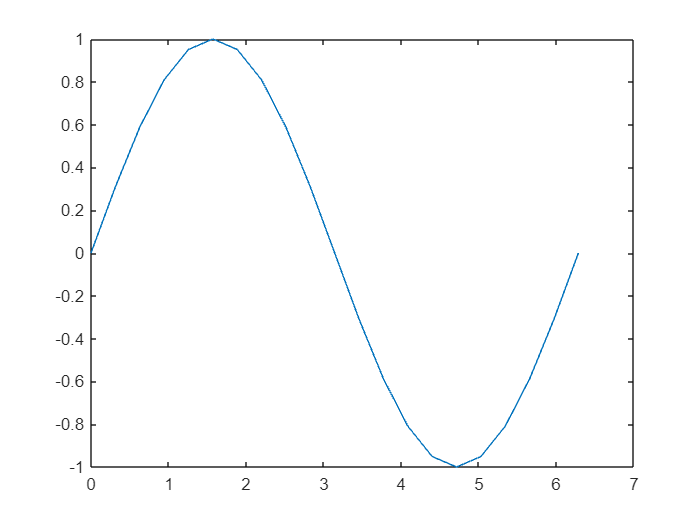

plot(x,y)

Zad f

Wyznacz średnią z wektora y. Jaki wymiar będzie miał rezultat? 

mean(y)

ans = -2.4880e-17

Zad g

Spróbuj rozwiązać następujący układ równań (wskazówka – sprawdź rząd macierzy oraz zapoznaj się z dokumentacją- rozdział:” Inverses and Determinants” ).

v_ans = [5; 1; -5]

v_ans =      5
     1
    -5


M_eq = [[1, 2, 3]; [-1, 1, 4]; [-1, -2, -3]]

M_eq =      1     2     3
    -1     1     4
    -1    -2    -3


det(M_eq)

ans = 0

Wyznacznik zero ergo nie ma rozwiązań.

Zad h

Wczytaj do MATLABa dane z pliku exampledata.mat (kliknij 2x na plik w przeglądarce plików środowiska MATLAB „Current folder”), a następnie sprawdź jakie zmienne zostały zaimportowane do MATLABa (przeglądarka przestrzeni roboczej „Workspace browser”). - Tablica RGB ma trzy wymiary (M-wierszy, N-kolumn i K-warstw) i reprezentuje obraz w formacie RGB o rozmiarze [M,N]. Każda warstwa zawiera wartość osobnej składowej koloru pikseli obrazu.  - Dokonaj konwersji każdego piksela obrazu korzystając ze wzoru 

load exampledata.mat
R= RGB(:,:,1);
G=RGB(:,:,2);
B=RGB(:,:,3);

Rw= R(:)';
Gw= G(:)';
Bw=B(:)';

A=[Rw; Gw; Bw];
Temp1=[0; 128;128]

Temp1 =      0
   128
   128


Temp2=[ 0.299 0.587 0.114; -0.169 -0.331 0.5; 0.5 -0.419 -0.081]

Temp2 =     0.2990    0.5870    0.1140
   -0.1690   -0.3310    0.5000
    0.5000   -0.4190   -0.0810


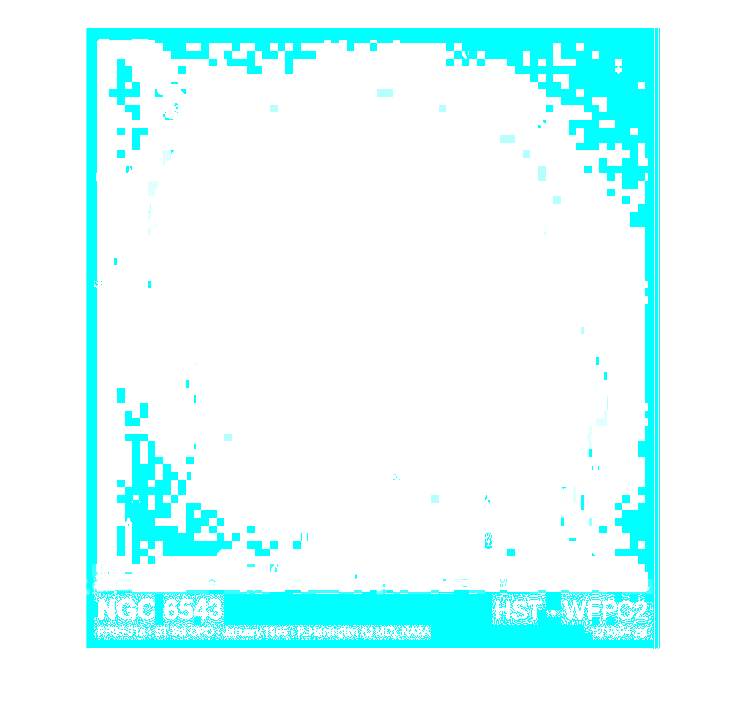


B= Temp1+ Temp2*A;
Y = B(1,:);
Cb = B(2,:);
Cr = B(3,:);

Y = reshape(Y,[650,600]);
Cb = reshape(Cb, [650, 600]);
Cr = reshape(Cr, [650, 600]);

YCbCr = Y;
YCbCr(:,:,2) = Cb;
YCbCr(:,:,3) = Cr;

imshow(YCbCr)

Zad i

Utwórz następujące zmienne: a=pi; b=ones(1,1, 'uint8');  a następnie dodaj je do siebie tak aby uzyskać rezultat w typie danych double (wskazówka: dokonaj odpowiedniej konwersji typów danych). 

a = pi

a = 3.1416

b=ones(1,1, 'uint8')

b = uint8
1

c = double(a) + double(b)

c = 4.1416

Zad j

Wygeneruj losowy ciąg znaków (tablica znakowa o rozmiarze [10x1]) składający się z następujących liter: a,b,c,d,e,f,g. Wskazówka – wykorzystaj funkcję randi do utworzenia wektora liczb pseudolosowych całkowitoliczbowych.  

letters = ['a', 'b', 'c', 'd', 'e', 'f', 'g']

letters = 'abcdefg'

q = 'abcdefghij'

q = 'abcdefghij'

for v = 1:10
q(v) = letters(randi(7));
end
q

q = 'bfagfdebdg'